clear variables
load('Tests/RPC_TT_test/e1_LPF/rpc_e1_samples_d10.mat')

[~,n_fpoint] = size(vouts_train2);
m = 1;
freq_out = 100;
x_train = training_samples2(1:2000,:);
y_train = vouts_train2(1:2000,freq_out);
y_test = vouts_test(:,freq_out);

lambda = 0.3;

[n_train,d] = size(x_train);
n_y = 1;

sample_polynomial_mat = ones(n_train,1);
n_tensor = 2^d;
for j = 1:d
    sample_polynomial_mat = [sample_polynomial_mat lambda*sample_polynomial_mat.*x_train(:,j)];
end
Phi = sample_polynomial_mat;

n_rpc = zeros(n_tensor,n_y);
d_rpc = zeros(n_tensor,n_y);
n_iterations = zeros(n_y,1);
for i = 1:n_y
    [n_rpc(:,i),d_rpc(:,i),n_iterations(i)] = sk_solve(Phi,y_train(:,i),5e-3,20);
end

N = 2*ones(1,10);
n_rpc_tt = tt_tensor(reshape(n_rpc,N));
d_rpc_tt = tt_tensor(reshape(d_rpc,N));

r_n = rank(n_rpc_tt);
r_d = rank(d_rpc_tt);

n_tt2 = cell(d,1);
d_tt2 = cell(d,1);
for i = 1:d
    n_tt2{i} = reshape(n_rpc_tt{i},[r_n(i)*2 r_n(i+1)]);
    d_tt2{i} = reshape(d_rpc_tt{i},[r_d(i)*2 r_d(i+1)]);
end


n_round = TTrounding(n_tt2,1e-5,3);
d_round = TTrounding(d_tt2,1e-5,3);

n2 = reshape(TTfull(n_round),[],1);
d2 = reshape(TTfull(d_round),[],1);


norm(n2-n_rpc)

ans = 0.0281

norm(d2-d_rpc)

ans = 0.6365

n_tt_temp = n_tt2;
n_tt_temp{d+1} = [1; 0];

d_tt_temp = d_tt2;
d_tt_temp{d+1} = [0; 1];

nd_tt = TTaxby(1,n_tt_temp,1,d_tt_temp);
nd_round = TTrounding(nd_tt,1d-5,2);

r = TTranks(nd_round);
n_round3 = nd_round(1:d);
n_round3{d} = n_round3{d}*nd_round{d+1}(1:r(d+1));
d_round3 = nd_round(1:d);
d_round3{d} = d_round3{d}*nd_round{d+1}(r(d+1)+1:end);


n3 = reshape(TTfull(n_round3),[],1);
d3 = reshape(TTfull(d_round3),[],1);


norm(n3-n_rpc)

ans = 0.8290

norm(d3-d_rpc)

ans = 1.7398

[y_predict4,nd_4,n_iterations] = rpc_TT(x_train,y_train,nd_round,test_samples,1,'Hermite',...
    lambda,0.1,1e-3,0.9,8);

ans =    14.5943    0.9899


ans =     0.9899    0.9673


ans =     0.9673    1.1706


ans =     1.1706    0.9235


ans =     0.9235    0.7172


ans =     0.7172    0.5107


ans =     0.5107    0.3673


ans =     0.3673    0.2859


ans =     0.2859    0.2239


ans =     0.2239    0.1573


ans =     0.1573    0.1333


ans =     0.1333    0.1037


ans =     0.1037    0.0929


ans =     0.0929    0.0745


ans =     0.0745    0.0670


ans =     0.0670    0.0572


ans =     0.0572    0.0541


ans =     0.0541    0.0456


ans =     0.0456    0.0504


ans =     0.0504    0.0375


ans =     0.0375    0.0349


ans =     0.0349    0.0316


ans =     0.0316    0.0306


ans =     0.0306    0.0268


ans =     0.0268    0.0265


ans =     0.0265    0.0226


ans =     0.0226    0.0215


ans =     0.0215    0.0191


ans =     0.0191    0.0184


ans =     0.0184    0.0156


ans =     0.0156    0.0148


ans =     0.0148    0.0135


ans =     0.0135    0.0128


ans =     0.0128    0.0121


ans =     0.0121    0.0118


ans =     0.0118    0.0112


ans =     0.0112    0.0110


ans =     0.0110    0.0107


ans =     0.0107    0.0105


ans =     0.0105    0.0103


ans =     0.0103    0.0101


ans =     0.0101    0.0100


ans =     0.0100    0.0099


ans =     0.0099    0.0098


ans =     0.0098    0.0097


ans =     0.0097    0.0097


ans =     0.0097    0.0097


ans =     0.0097    0.0096



nd_4 = nd_4{1};
r = TTranks(nd_4);
n_round4 = nd_4(1:d);
n_round4{d} = n_round4{d}*nd_4{d+1}(1:r(d+1));
d_round4 = nd_4(1:d);
d_round4{d} = d_round4{d}*nd_4{d+1}(r(d+1)+1:end);


n4 = reshape(TTfull(n_round4),[],1);
d4 = reshape(TTfull(d_round4),[],1);


norm(n4-n_rpc)

ans = 0.1444

norm(d4-d_rpc)

ans = 0.2098


[n_test,~] = size(test_samples);
xi_test = ones(n_test,1);
for j = 1:d
    xi_test = [xi_test lambda*xi_test.*test_samples(:,j)];
end
y_predict = (xi_test*n_rpc)./(xi_test*d_rpc);

test_samples_tensor = genPolynomialSamplesTensor(test_samples,1,'Hermite');
y_predict2 =  multi_r1_times_TT(test_samples_tensor,n_round)./multi_r1_times_TT(test_samples_tensor,d_round);
y_predict3 =  multi_r1_times_TT(test_samples_tensor,n_round3)./multi_r1_times_TT(test_samples_tensor,d_round3);

norm(y_predict-y_test)/norm(y_test)

ans = 1.7021e-11

norm(y_predict2-y_test)/norm(y_test)

ans = 1.1266

norm(y_predict3-y_test)/norm(y_test)

ans = 1.0369

norm(y_predict4-y_test)/norm(y_test)

ans = 0.0136

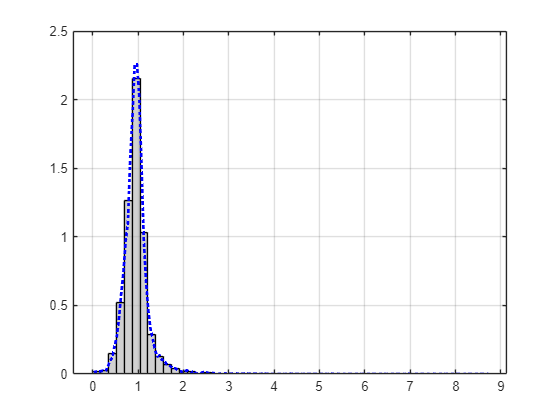



f = figure(5);
Hmc = histogram(abs(vouts_test(:,100)) ,50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N_mc,edges] = histcounts(abs(y_predict4), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_mc,'b:','LineWidth',2)